recObj = audiorecorder

recObj =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


recDuration = 3;
disp("Begin speaking.")

Begin speaking.


recordblocking(recObj,recDuration);
disp("End of recording.")

End of recording.


play(recObj);

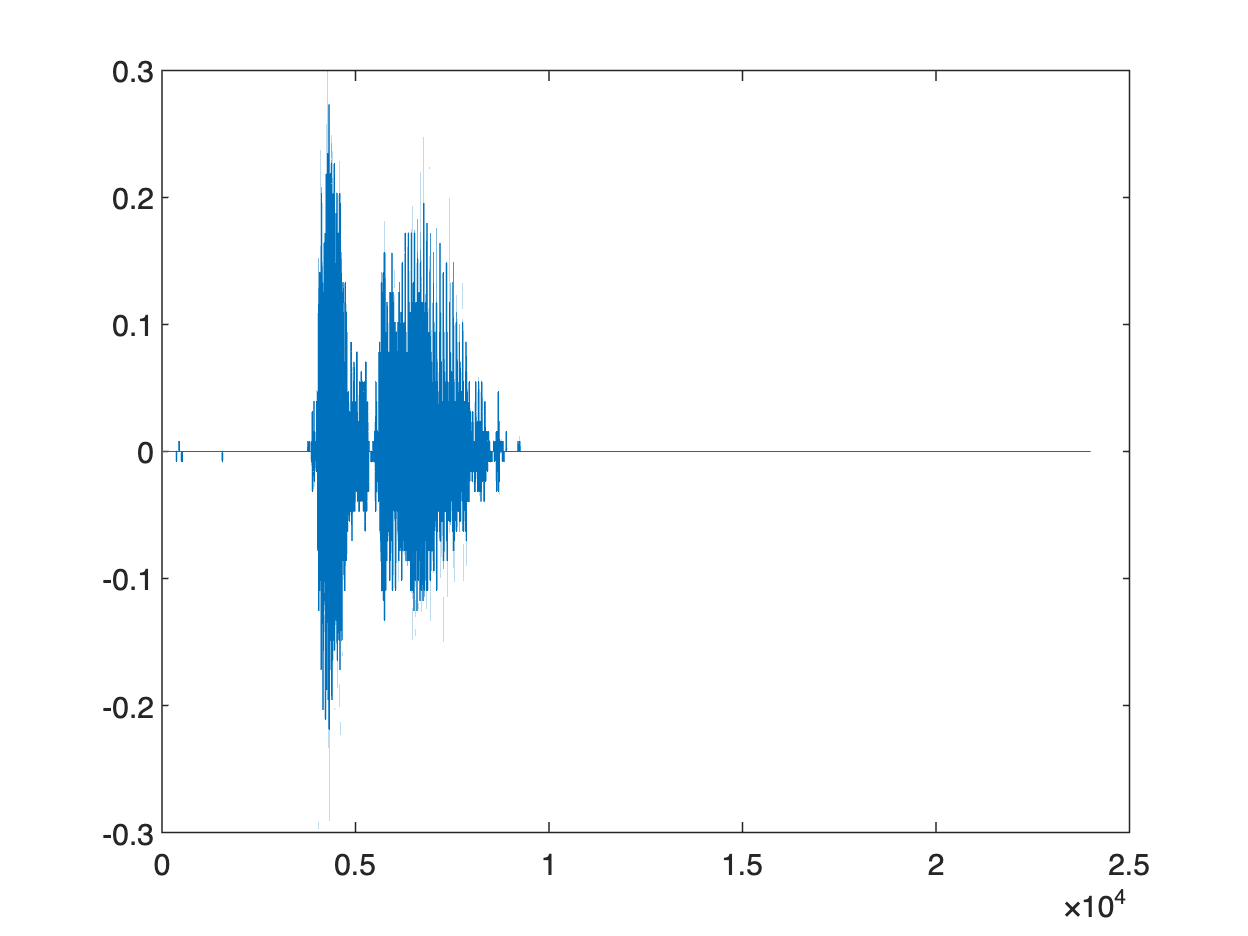

y = getaudiodata(recObj);
plot(y);

Analysis

transcriber = speechClient("wav2vec2.0")

transcriber =   Wav2VecSpeechClient with properties:

    Segmentation: 'word'
      TimeStamps: 0


transcript = speech2text(transcriber,y,recObj.SampleRate)

transcript = 2×2 table
    Transcript    Confidence
    __________    __________

      "the"        0.86763  
      "dog"        0.99986  



words = transcript{:,1}

words = 2×1 string array
    "the"
    "dog"


% corret = 0
% function correct = check(res,var) 

corret = 0

% for i = 1:length(res)
%     if res{i} == "dog"
%          correct = true
%         break 
%     end
% end

correct = logical
   1


% corret

corret = 0

res = loqu_check(words,"dog")

res = logical
   1
